# Antenna radiation pattern calculator

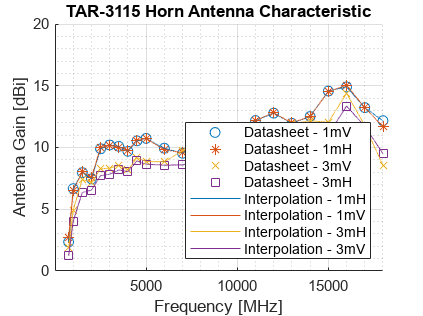


database_file = '../output/antmeas_test.db';

cmd_proc_import_sitedata(database_file,'Site19_KIT', '../input_cal/Measurement_Site_19_KIT/20221126_SiteCal_ETS3115_HornBothSide.s2p', 1.0);
cmd_proc_import_antenna_ETS3115(database_file, '../input_cal/Datasheet_HornAnttena_ETS3115/', 1.0);

cmd_proc_generate_sitecalval(database_file);

pyrunfile('radpat_csv2sqlite.py');

% cmd_proc_generate_dutgain(database_file, 'dut_gains', 'site_calval_TAR3115_dataset_Data3mV');
